%% Init
clear; clc;
global BOX_DIR
global RECONDIR
global DUKEDIR
BOX_DIR=[userpath '\..\..\Box'];
%userpath is usually %USERPROFILE%/Documents/MATLAB, so move up two
%directories to get to %USERPROFILE%/Box
RECONDIR=[BOX_DIR '\ECoG_Recon'];
DUKEDIR = [BOX_DIR '\CoganLab\D_Data\SentenceRep'];
path = fullfile(userpath, 'MATLAB-env' );
addpath(genpath(path));

%% Task
Task=[];
Task.Name='SentenceRep';

Task.Base.Name='Start';
Task.Base.Epoch='Start';
Task.Base.Time=[-1000 -500];

% old nyu baseline (deprecated)
% Task.Base.Name='AuditoryPre';
% Task.Base.Epoch='Auditory';
% Task.Base.Time=[-500 0];

% 5 conds
Task.Conds(1).Name='LSwords';
Task.Conds(1).Field(1).Name='AuditorywDelay';
Task.Conds(1).Field(1).Epoch='Auditory';
Task.Conds(1).Field(1).Time=[-500 1500];
Task.Conds(1).Field(2).Name='DelaywGo';
Task.Conds(1).Field(2).Epoch='Go';
Task.Conds(1).Field(2).Time=[-500 1500];
Task.Conds(1).Field(3).Name='AuditorytoResponse';
Task.Conds(1).Field(3).Epoch='Auditory';
Task.Conds(1).Field(3).Time=[-1000 3000];
Task.Conds(1).Field(4).Name='Response';
Task.Conds(1).Field(4).Epoch='ResponseStart';
Task.Conds(1).Field(4).Time=[-1000 1000];

Task.Conds(2).Name='LSsentences';
Task.Conds(2).Field(1).Name='AuditorywDelay';
Task.Conds(2).Field(1).Epoch='Auditory';
Task.Conds(2).Field(1).Time=[-500 5000];
Task.Conds(2).Field(2).Name='DelaywGo';
Task.Conds(2).Field(2).Epoch='Go';
Task.Conds(2).Field(2).Time=[-500 4000];
Task.Conds(2).Field(3).Name='Response';
Task.Conds(2).Field(3).Epoch='ResponseStart';
Task.Conds(2).Field(3).Time=[-1000 4000];

Task.Conds(3).Name='JLwords';
Task.Conds(3).Field(1).Name='AuditorywDelay';
Task.Conds(3).Field(1).Epoch='Auditory';
Task.Conds(3).Field(1).Time=[-500 1500];
Task.Conds(3).Field(2).Name='DelaywGo';
Task.Conds(3).Field(2).Epoch='Go';
Task.Conds(3).Field(2).Time=[-500 1500];
Task.Conds(3).Field(3).Name='AuditorytoResponse';
Task.Conds(3).Field(3).Epoch='Auditory';
Task.Conds(3).Field(3).Time=[-1000 3000];

Task.Conds(4).Name='JLsentences';
Task.Conds(4).Field(1).Name='AuditorywDelay';
Task.Conds(4).Field(1).Epoch='Auditory';
Task.Conds(4).Field(1).Time=[-500 5000];
Task.Conds(4).Field(2).Name='DelaywGo';
Task.Conds(4).Field(2).Epoch='Go';
Task.Conds(4).Field(2).Time=[-500 4000];

Task.Conds(5).Name='LMwords';
Task.Conds(5).Field(1).Name='AuditorywDelay';
Task.Conds(5).Field(1).Epoch='Auditory';
Task.Conds(5).Field(1).Time=[-500 1500];
Task.Conds(5).Field(2).Name='DelaywGo';
Task.Conds(5).Field(2).Epoch='Go';
Task.Conds(5).Field(2).Time=[-500 1500];
Task.Conds(5).Field(3).Name='AuditorytoResponse';
Task.Conds(5).Field(3).Epoch='Auditory';
Task.Conds(5).Field(3).Time=[-1000 3000];
Task

Task = struct with fields:
     Name: 'SentenceRep'
     Base: [1×1 struct]
    Conds: [1×5 struct]


%% Load and Epoch Subject Data
if ~exist('Subject','var')
    Subject = popTaskSubjectData(Task);
end

Task = SentenceRep
Task Directory = C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep
D12
	RAIP
	RAMP
	RASF
	RASP
	RMIP
	RMMP
	RMSF
	RPIF
	RPMP
	RPSF
	RPSP


D14
	RAIP
	RAMP
	RAMT
	RMMF
	RMSF
	RMSP
	RMST
	RPIF
	RPIP
	RPMF
	RPSF
	RPST


D15
	LAIT
	LAMF
	LAMT
	LMMF
	LMMT
	LMST
	LPIF
	LPIT
	LPST
	RAMT
	RASF
	RPIT


D16
	LAST
	LMST
	LPST
	LTG


D17
	LASF
	LMMF
	LMSF
	LPSF
	RAIF
	RAMF
	RASF
	RMIF
	RMSF
	RPIF
	RPMF
	RPSF


D18
	LAMF
	LASF
	LAST
	LMSF
	LPIF
	LPMF
	LPMT
	LPSF
	RASF
	RAST
	RMSF
	RPMT
	RPSF


D20
	LAIF
	LAMF
	LAOF
	LASF
	LMIF
	LMSF
	LPIF
	LPMF
	LPSF
	RAIF
	RMSF
	RPIF


D22
	LAIP
	LAMF
	LAMP
	LASP
	LMIF
	LMSF
	LMSP
	LPIF
	LPMF
	LPSF


D23
	R1MF
	R2IF
	R2MF
	RAIF
	RAMF
	RASF
	RMSF
	RPIF
	RPMF
	RPSF


D24
	LAST
	LAT
	LMST
	LOF
	LPST
	LTG


D26
	RAST
	RAT
	RPG
	RPST
	RTG


D27
	LAI
	LAIF
	LAMF
	LAMT
	LMMT
	LMSF
	LMST
	LPI
	LPIF
	LPMT
	LPSF
	LPST


D28
	LAI
	LAIF
	LAIO
	LAMF
	LAMO
	LAMT
	LMST
	LPI
	LPIO
	LPMF
	LPMT
	LPST


D29
	LAIP
	LASF
	LASP
	LMMF
	LMSF
	LPMF
	LPSF
	RAIP
	RASF
	RASP
	RMMF
	RMSF
	RPMF
	RPSF


D3
	LAST
	LMST
	LOF
	LPST
	LTG
	LTP


D30
	RAIP
	RAMF
	RAMP
	RASF
	RASP
	RMIP
	RMMF
	RMMP
	RMSP
	RPIP
	RPMF
	RPMP


D31
	LAIF
	LASF
	LIP
	LMMF
	LMSF
	LPMF
	LPSF
	LSP
	RAIF
	RASF
	RIP
	RMMF
	RMSF
	RPMF
	RPSF
	RSP


D32
	LAI
	LAIF
	LAMT
	LMIF
	LMMT
	LMST
	LOF
	LPI
	LPIF
	LPIT
	LPMT
	LPST


D5
	ASTI
	ASTII
	LTG
	MST
	PST


D53
	LAIF
	LAMT
	LMST
	LOF
	LPI
	LPIF
	RAIF
	ROF
	RPI
	RPIF
	RPMT


D57
	LAMT
	LMMT
	RAI
	RAIF
	RAIT
	RAMF
	RAMT
	RAST
	RMMF
	RMMT
	RPI
	RPIP
	RPIT
	RPMT


D59
	LAIP
	LAMP
	LASP
	LAT
	LMIF
	LMMF
	LMMT
	LMPF
	LMPT
	LMSF
	LPIF
	LPSF
	LPT


D6
	LAIF
	LASF
	LAST
	LMST
	LPP
	LPST
	LTG


D60
	LAMT
	LASF
	LI
	LMMT
	LPIF
	LPIP
	LPIT
	LPMT
	LPST
	RAMT
	RASF
	RI
	RMMT
	RPIF
	RPIP
	RPIT
	RPMT
	RPST


D61
	LAI
	LAIF
	LAIP
	LAMF
	LAMT
	LMMF
	LMST
	LOF
	LPI
	LPIF
	LPIT
	LPMF
	LPST
	RMST
	ROF
	RPMF


D65
	RAIO
	RAMT
	RASF
	RI
	RMIP
	RMMP
	RMMT
	RMSF
	ROF
	RPIF
	RPIP
	RPIT
	RPMP
	RPMT
	RPST


D66
	ROAI
	ROAM
	ROAS
	ROPI
	ROPM
	RPIP
	RPMP
	RPSP
	RTAI
	RTAM
	RTMM
	RTPI
	RTPM
	RTPS


D69
	LOF
	LPM
	LPS
	LTAI
	LTAM
	LTAS
	LTMI
	LTMM
	LTMS
	LTPI
	LTPM
	LTPS


D7
	RAIH
	RAMF
	RASF
	RFG
	RMIH
	RPIH
	RPO
	RPPH


D70
	LFAI
	LFAS
	LFO
	LFPI
	LIA
	LIP
	LTAI
	LTAM
	LTMI
	LTMM
	LTMP
	LTMS
	LTPI
	LTPS
	RFAI
	RFO
	RTAM
	RTMM


D71
	RFO
	RIA
	RIP
	RO
	RTAM
	RTAS
	RTMM
	RTMS
	RTPI
	RTPM
	RTPS


D73
	LFAI
	LFAM
	LFAP
	LFAS
	LFL
	LFMM
	LFMS
	LFPM
	LFPS
	LPAM
	LPAS
	LPL
	LPMM
	LPMS
	LPPS


D8
	LA
	LB
	LC
	LD
	RA
	RB
	RC
	RD
	RE
	RF
	RG


D9
	LAMT
	LASF
	LMIF
	LMMF
	LMST
	LPMT
	LPSF
	RAMT
	RASF
	RMIF
	RMMF
	RMPT
	RMST
	RPSF



chanBinAll = loadTaskSubjectData(Task,Subject,DUKEDIR);

iSN = 1

iSN = 2

iSN = 3

iSN = 4

iSN = 5

iSN = 6

iSN = 7

iSN = 8

iSN = 9

iSN = 10

iSN = 11

iSN = 12

iSN = 13

iSN = 14

iSN = 15

iSN = 16

iSN = 17

iSN = 18

iSN = 19

iSN = 20

iSN = 21

iSN = 22

iSN = 23

iSN = 24

C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D61_SentenceRep_LSwords_Response_Start.mat has not yet been created
C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D61_SentenceRep_LSsentences_Response_Start.mat has not yet been created


iSN = 25

C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D65_SentenceRep_LSwords_Response_Start.mat has not yet been created
C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D65_SentenceRep_LSsentences_Response_Start.mat has not yet been created


iSN = 26

C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D66_SentenceRep_LSwords_Response_Start.mat has not yet been created
C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D66_SentenceRep_LSsentences_Response_Start.mat has not yet been created


iSN = 27

C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D69_SentenceRep_LSwords_Response_Start.mat has not yet been created
C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D69_SentenceRep_LSsentences_Response_Start.mat has not yet been created


iSN = 28

iSN = 29

C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D70_SentenceRep_LSwords_Response_Start.mat has not yet been created
C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D70_SentenceRep_LSsentences_Response_Start.mat has not yet been created


iSN = 30

C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D71_SentenceRep_LSwords_Response_Start.mat has not yet been created
C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D71_SentenceRep_LSsentences_Response_Start.mat has not yet been created


iSN = 31

C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D73_SentenceRep_LSwords_Response_Start.mat has not yet been created
C:\Users\ae166\Documents\MATLAB\..\..\Box\CoganLab\D_Data\SentenceRep\Stats\timePerm\D73_SentenceRep_LSsentences_Response_Start.mat has not yet been created


iSN = 32

iSN = 33

iSN = 34


% Remove Unprocessed Data
Subject_old = Subject;
chanBinAll_old = chanBinAll;
Subject = Subject_old(~cellfun('isempty',chanBinAll_old));
chanBinAll = chanBinAll_old(~cellfun('isempty',chanBinAll_old));
if isequal(Subject_old, Subject)
    clear Subject_old chanBinAll_old
end

## Calculate Channel Significance

global sigMatChansName
[sigChans, sigMatA, allSigZ, sigMatChansName, sigMatChansLoc] = getChanSigs(Task, Subject, chanBinAll);

iC = 1

iC = 2

iC = 3

iC = 4

iC = 5

%save('data.mat','sigChans','sigMatA','allSigZ','sigMatChansName','sigMatChansLoc','Task','Subject')
%save('chanbinall.mat','chanBinAll','Subject','Task','-v7.3')

## Compile Significant Channels

%load('../data/pydata.mat')
sigMatStartTime=struct;
sigMatLength=struct;
for iC=1:size(chanBinAll{1},2)
    cond = Task.Conds(iC).Name;
    for iF=1:size(chanBinAll{1}{iC},2)
        field = Task.Conds(iC).Field(iF).Name;
        for iChan=1:size(sigChans.(cond).(field),1)
            ii=find(sigMatA.(cond).(field)(sigChans.(cond).(field)(iChan),:)==1);
            sigMatStartTime.(cond).(field)(iChan)=ii(1);
            sigMatLength.(cond).(field)(iChan)=length(ii);
        end
    end
end

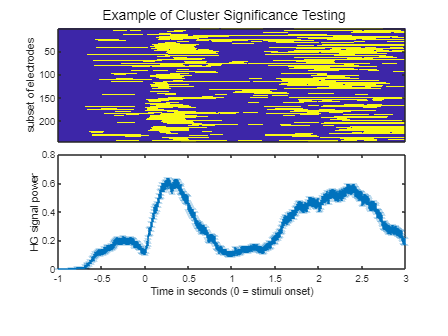


%% Define Electrodes by Epoch Activity

% initial way
% AUD1=intersect(sigChans.LSwords.AuditorywDelay,sigChans.LMwords.AuditorywDelay); % LS LM
% AUD2=intersect(AUD1,sigChans.JLwords.AuditorywDelay); % LS/LM JL
% PROD1=intersect(sigChans.LSwords.DelaywGo,sigChans.LMwords.DelaywGo); % LS LM
% SM=intersect(AUD1,PROD1); % Sensory Motor
% AUD=setdiff(AUD2,SM); % Auditory
% PROD=setdiff(PROD1,SM); %

% new way?
[AUDLS, ~]=find(sigMatA.LSwords.AuditorywDelay(:,51:175) == 1);
AUDLS=unique(AUDLS);
AUDLS=intersect(AUDLS,sigChans.LSwords.AuditorywDelay);

[AUDLM, ~]=find(sigMatA.LMwords.AuditorywDelay(:,51:175) == 1);
AUDLM=unique(AUDLM);
AUDLM=intersect(AUDLM,sigChans.LMwords.AuditorywDelay);

[AUDJL, ~]=find(sigMatA.JLwords.AuditorywDelay(:,51:175) == 1);
AUDJL=unique(AUDJL);
AUDJL=intersect(AUDJL,sigChans.JLwords.AuditorywDelay);

AUD1=intersect(AUDLS,AUDLM);
AUD2=intersect(AUD1,AUDJL);
PROD1=intersect(sigChans.LSwords.DelaywGo,sigChans.LMwords.DelaywGo); % LS LM
SM=intersect(AUD1,PROD1); % Sensory Motor
AUD=setdiff(AUD2,SM); % Auditory
PROD=setdiff(PROD1,SM); %

[~, idxSM]=intersect(sigChans.LSwords.AuditorywDelay,SM);
[~, idxAUD]=intersect(sigChans.LSwords.AuditorywDelay,AUD);

iiSM=find(sigMatStartTime.LSwords.AuditorywDelay(idxSM)>=50);
iiAUD=find(sigMatStartTime.LSwords.AuditorywDelay(idxAUD)>=50);

% these are significant channels that start after aud onset
SM2=intersect(SM,sigChans.LSwords.AuditorywDelay(idxSM(iiSM)));
AUD2=intersect(AUD,sigChans.LSwords.AuditorywDelay(idxAUD(iiAUD)));
PROD2=setdiff(PROD1,SM2);

Locs = find(~contains(sigMatChansName.LSwords.AuditorywDelay, '-L'));
SML = setdiff(SM,Locs);
SML2 = setdiff(SM2,Locs);

Locs = find(~contains(sigMatChansName.LSwords.AuditorywDelay, '-R'));
SMR = setdiff(SM,Locs);
SMR2 = setdiff(SM2,Locs);

AUDresp = AUD(AUD<=length(sigMatA.LSwords.Response));
SMresp = SM(SM<=length(sigMatA.LSwords.Response));
PRODresp = PROD(PROD<=length(sigMatA.LSwords.Response));

AUDresp2 = AUD2(AUD2<=length(sigMatA.LSwords.Response));
SMresp2 = SM2(SM2<=length(sigMatA.LSwords.Response));
PRODresp2 = PROD2(PROD2<=length(sigMatA.LSwords.Response));

SMrespL = SML(SML<=length(sigMatA.LSwords.Response));

clear AUD1 PROD1 AUDLS AUDLM AUDJL iiSM iiAUD SMLS idxSM idxAUD

LSsig = getchans(sigChans,['AuditorytoResponse']);
figure;
[tstart, tend] = getEpochFromName(Task,'LSwords','AuditorytoResponse');
tscale=linspace(tstart,tend,(tend-tstart)/10)/1000;
subplot(2,1,1)
imagesc(sigMatA.LSwords.AuditorytoResponse(SM,:))
ylabel("subset of electrodes")
set(gca,'xtick',[])
s = subplot(2,1,2);
plot_signal(sigMatA.LSwords.AuditorytoResponse(SM,:),tscale)
set(s, 'Units', 'normalized');
pos = get(s, 'Position');
pos(2)=0.2;
set(s,'Position',pos)
ylabel("HG signal power")
xlabel("Time in seconds (0 = stimuli onset)")
sgtitle("Example of Cluster Significance Testing")

LSwords


d = 'Zscores'

factorizing AUD
factorizing SM
factorizing PROD


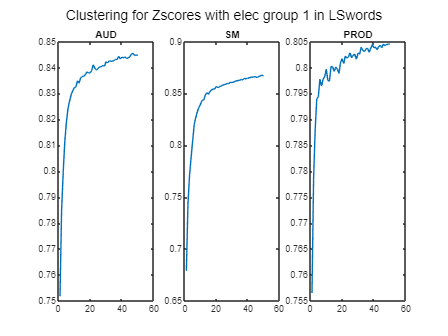

d = 'BinarySignificance'

factorizing AUD
factorizing SM
factorizing PROD


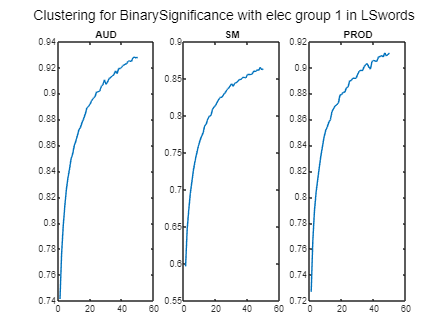

%% What is the signal?
% option.threshold = 0.01;
% option.numClasses = 4;
% option.rerun = 10;
% [k,rho,kSuggested] = chooseBestk(sig, option);
D_list = [];
All = [SMresp;AUDresp;PRODresp];
AllAll = getchans(sigChans,["None"]);
AllAll = AllAll(AllAll<=length(sigMatA.LSwords.Response));
elecs = {AUD,SM,PROD};
elecnames = {'AUD','SM','PROD'};
timescale = 1:50;
dat = struct('Zscores', allSigZ, 'BinarySignificance', sigMatA);
options = statset('Display','off');
Conds = {'LSwords'};
for cond=Conds
    disp(cond{:})
    for d=fieldnames(dat)'
        d=d{1}
        for k=1
            figure
            for j=1:length(elecs)
                if j==1
                    ylabel(sprintf("fit using %s", d ))
                end
                ind = j+(k-1)*3;
                idxs=elecs{ind};
                fprintf('factorizing %s\n',elecnames{ind})
                sigs = [dat.(d).(cond{:}).AuditorywDelay(idxs,1:175),...
                    dat.(d).(cond{:}).DelaywGo(idxs,:)];
                for i=timescale
                    [~,~,D_list(i)]=nnmf(sigs,i, ...
                        'Replicates',10,...
                       'Algorithm','mult','options',options);
                end
                subplot(1,length(elecs),j)
                plot(timescale,1-D_list(timescale))
                title(sprintf('%s',elecnames{ind}))
                
            end
            sgtitle(sprintf('Clustering for %s with elec group %d in %s',d,k,cond{:}))
       end
    end
end

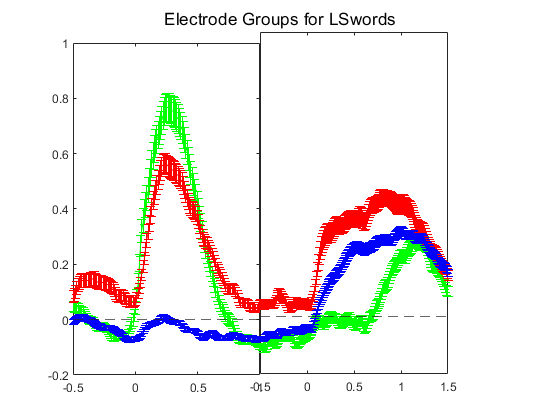

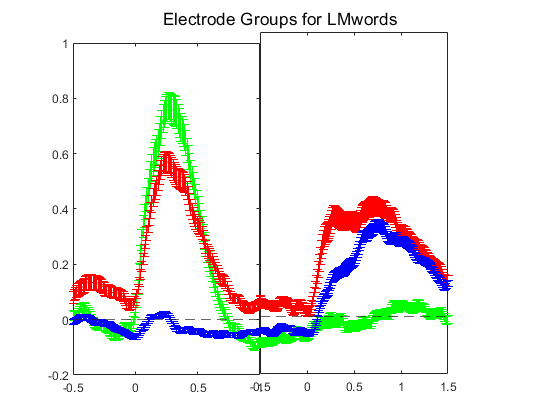

elecs = {AUD,SM,PROD};
colors = {'g','r','b'};
conds = {'LSwords','LMwords','JLwords'};
for cond = conds
    plot_together(Task, allSigZ, elecs, cond{:}, {'AuditorywDelay','DelaywGo'},{[-0.5,1],[-0.5,1.5]},colors);
    sgtitle(['Electrode Groups for ' cond{:}])
    % legend('AUD','SM','PROD')
end

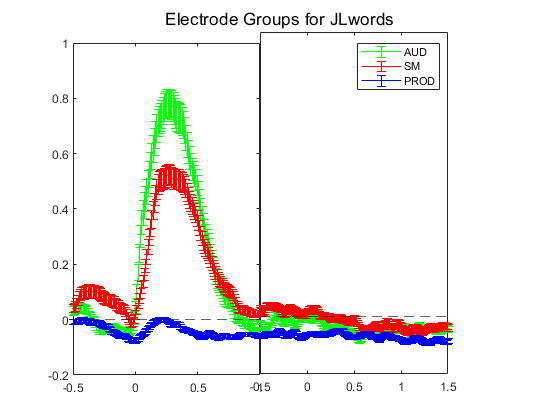

legend('AUD','SM','PROD')
ylim([-0.2 1])

ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D12\elec_recon\D12.FSAVERAGE
D12 110


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D14\elec_recon\D14.FSAVERAGE
D14 120


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D15\elec_recon\D15.FSAVERAGE
D15 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D16\elec_recon\D16.FSAVERAGE
D16 41


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D17\elec_recon\D17.FSAVERAGE
D17 114


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D18\elec_recon\D18.FSAVERAGE
D18 132


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D20\elec_recon\D20.FSAVERAGE
D20 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D22\elec_recon\D22.FSAVERAGE
D22 100


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D23\elec_recon\D23.FSAVERAGE
D23 121


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D24\elec_recon\D24.FSAVERAGE
D24 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D26\elec_recon\D26.FSAVERAGE
D26 60


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D27\elec_recon\D27.FSAVERAGE
D27 114


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D28\elec_recon\D28.FSAVERAGE
D28 108


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D29\elec_recon\D29.FSAVERAGE
D29 140


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D3\elec_recon\D3.FSAVERAGE
D3 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D30\elec_recon\D30.FSAVERAGE
D30 104


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D31\elec_recon\D31.FSAVERAGE
D31 160


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D32\elec_recon\D32.FSAVERAGE
D32 158


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D5\elec_recon\D5.FSAVERAGE
D5 48


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D53\elec_recon\D53.FSAVERAGE
D53 158


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D57\elec_recon\D57.FSAVERAGE
D57 178


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D59\elec_recon\D59.FSAVERAGE
D59 184


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D6\elec_recon\D6.FSAVERAGE
D6 96


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D60\elec_recon\D60.FSAVERAGE
D60 252


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D61\elec_recon\D61.FSAVERAGE
D61 232


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D65\elec_recon\D65.FSAVERAGE
D65 220


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D66\elec_recon\D66.FSAVERAGE
D66 182


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D69\elec_recon\D69.FSAVERAGE
D69 132


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D7\elec_recon\D7.FSAVERAGE
D7 102


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D70\elec_recon\D70.FSAVERAGE
D70 202


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D71\elec_recon\D71.FSAVERAGE
D71 162


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D73\elec_recon\D73.FSAVERAGE
D73 200


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D8\elec_recon\D8.FSAVERAGE
D8 110


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D9\elec_recon\D9.FSAVERAGE
D9 140
Loading: C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\fsaverage\surf\lh.pial.mat


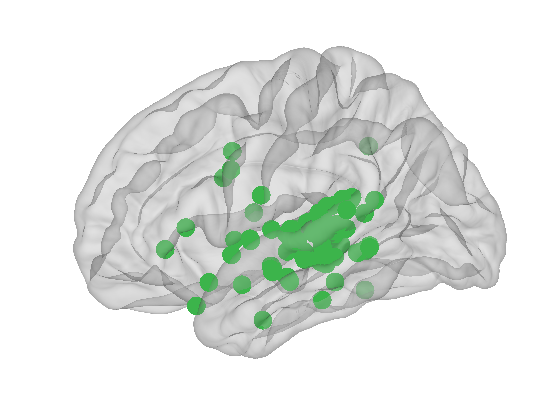

ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D12\elec_recon\D12.FSAVERAGE
D12 110


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D14\elec_recon\D14.FSAVERAGE
D14 120


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D15\elec_recon\D15.FSAVERAGE
D15 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D16\elec_recon\D16.FSAVERAGE
D16 41


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D17\elec_recon\D17.FSAVERAGE
D17 114


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D18\elec_recon\D18.FSAVERAGE
D18 132


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D20\elec_recon\D20.FSAVERAGE
D20 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D22\elec_recon\D22.FSAVERAGE
D22 100


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D23\elec_recon\D23.FSAVERAGE
D23 121


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D24\elec_recon\D24.FSAVERAGE
D24 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D26\elec_recon\D26.FSAVERAGE
D26 60


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D27\elec_recon\D27.FSAVERAGE
D27 114


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D28\elec_recon\D28.FSAVERAGE
D28 108


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D29\elec_recon\D29.FSAVERAGE
D29 140


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D3\elec_recon\D3.FSAVERAGE
D3 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D30\elec_recon\D30.FSAVERAGE
D30 104


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D31\elec_recon\D31.FSAVERAGE
D31 160


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D32\elec_recon\D32.FSAVERAGE
D32 158


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D5\elec_recon\D5.FSAVERAGE
D5 48


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D53\elec_recon\D53.FSAVERAGE
D53 158


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D57\elec_recon\D57.FSAVERAGE
D57 178


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D59\elec_recon\D59.FSAVERAGE
D59 184


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D6\elec_recon\D6.FSAVERAGE
D6 96


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D60\elec_recon\D60.FSAVERAGE
D60 252


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D61\elec_recon\D61.FSAVERAGE
D61 232


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D65\elec_recon\D65.FSAVERAGE
D65 220


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D66\elec_recon\D66.FSAVERAGE
D66 182


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D69\elec_recon\D69.FSAVERAGE
D69 132


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D7\elec_recon\D7.FSAVERAGE
D7 102


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D70\elec_recon\D70.FSAVERAGE
D70 202


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D71\elec_recon\D71.FSAVERAGE
D71 162


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D73\elec_recon\D73.FSAVERAGE
D73 200


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D8\elec_recon\D8.FSAVERAGE
D8 110


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D9\elec_recon\D9.FSAVERAGE
D9 140
Loading: C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\fsaverage\surf\lh.pial.mat


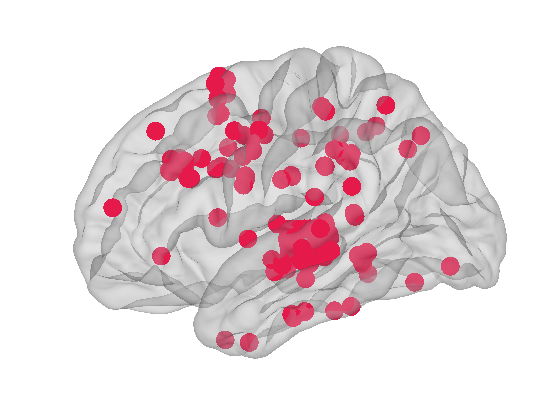

ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D12\elec_recon\D12.FSAVERAGE
D12 110


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D14\elec_recon\D14.FSAVERAGE
D14 120


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D15\elec_recon\D15.FSAVERAGE
D15 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D16\elec_recon\D16.FSAVERAGE
D16 41


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D17\elec_recon\D17.FSAVERAGE
D17 114


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D18\elec_recon\D18.FSAVERAGE
D18 132


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D20\elec_recon\D20.FSAVERAGE
D20 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D22\elec_recon\D22.FSAVERAGE
D22 100


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D23\elec_recon\D23.FSAVERAGE
D23 121


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D24\elec_recon\D24.FSAVERAGE
D24 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D26\elec_recon\D26.FSAVERAGE
D26 60


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D27\elec_recon\D27.FSAVERAGE
D27 114


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D28\elec_recon\D28.FSAVERAGE
D28 108


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D29\elec_recon\D29.FSAVERAGE
D29 140


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D3\elec_recon\D3.FSAVERAGE
D3 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D30\elec_recon\D30.FSAVERAGE
D30 104


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D31\elec_recon\D31.FSAVERAGE
D31 160


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D32\elec_recon\D32.FSAVERAGE
D32 158


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D5\elec_recon\D5.FSAVERAGE
D5 48


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D53\elec_recon\D53.FSAVERAGE
D53 158


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D57\elec_recon\D57.FSAVERAGE
D57 178


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D59\elec_recon\D59.FSAVERAGE
D59 184


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D6\elec_recon\D6.FSAVERAGE
D6 96


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D60\elec_recon\D60.FSAVERAGE
D60 252


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D61\elec_recon\D61.FSAVERAGE
D61 232


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D65\elec_recon\D65.FSAVERAGE
D65 220


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D66\elec_recon\D66.FSAVERAGE
D66 182


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D69\elec_recon\D69.FSAVERAGE
D69 132


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D7\elec_recon\D7.FSAVERAGE
D7 102


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D70\elec_recon\D70.FSAVERAGE
D70 202


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D71\elec_recon\D71.FSAVERAGE
D71 162


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D73\elec_recon\D73.FSAVERAGE
D73 200


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D8\elec_recon\D8.FSAVERAGE
D8 110


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D9\elec_recon\D9.FSAVERAGE
D9 140
Loading: C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\fsaverage\surf\lh.pial.mat


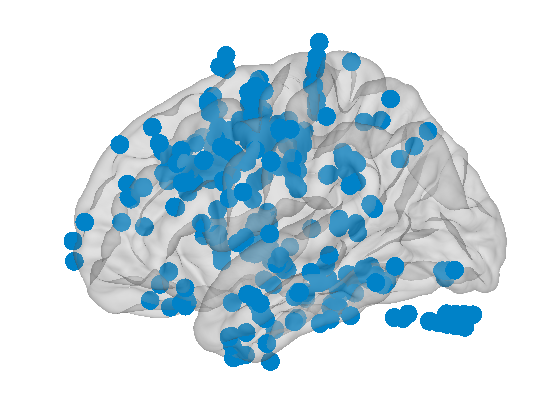

subj_labels=sigMatChansName.LSwords.AuditorywDelay;
mapping = [2,1,4];
for i = 1:3
    grouping=zeros(length(subj_labels),1);
    grouping(elecs{i})=mapping(i);
    cfg.hemisphere='l';
    cfg.show_labels=false;
    plot_subjs_on_average_grouping(subj_labels,grouping,'fsaverage',cfg);
%     cfg.hemisphere='r';
%     plot_subjs_on_average_grouping(subj_labels,grouping,'fsaverage',cfg);
end

%% Perform Non-Negative Matrix Factorization to Identify Subprocesses
idx=SM;
sig = allSigZ;
allsig = [sig.LSwords.AuditorywDelay(idx,1:175),sig.LSwords.DelaywGo(idx,:)];
sentsig = [sig.LSsentences.AuditorywDelay(idx,1:450),sig.LSsentences.DelaywGo(idx,:)];
audsig = [sig.LSwords.AuditorywDelay(idx,:)];%;;sig.LMwords.AuditorywDelay(idx,:);sig.JLwords.AuditorywDelay(idx,:)]
respsig = [sig.LSwords.AuditorywDelay(SMresp,1:150),sig.LSwords.Response(SMresp,:)];


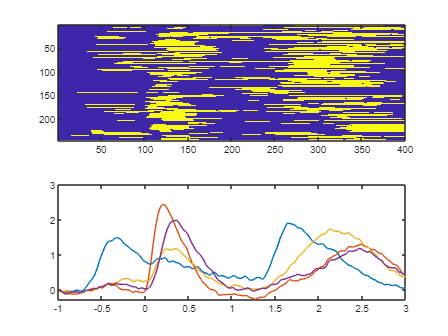

% Need to validate!
n_sigs = 4;%kSuggested;

% words
% idx=[idx;idx];
[W,H,D]=nnmf(allsig,n_sigs,'algorithm','mult','replicates',1000);
Wi = getSigMaxes(W);

figure;
[tstart, tend] = getEpochFromName(Task,'LSwords','AuditorytoResponse');
tscale=linspace(tstart,tend,(tend-tstart)/10)/1000;
subplot(2,1,1)
imagesc(sigMatA.LSwords.AuditorytoResponse(idx,:))
subplot(2,1,2)
plot(tscale,sig.LSwords.AuditorytoResponse(idx,:)'*W./size(W,1))


multi_idx = {};
% peakLatency = {};
% maxes = struct();
% peaks=struct();

for cond={'AuditorywDelay','DelaywGo','Response'}
%     h1 = figure;
%     h2 = figure;
%     ax2 = gca;
%     ind = idx(idx<=size(allSigZ.LSwords.(cond{:}),1)); % check for missing subjects in a given condition
%     ZSig = allSigZ.LSwords.(cond{:})(ind,:);
%     [tstart,tend] = getEpochFromName(Task,'LSwords',cond{:});
%     tstart = tstart./1000;
%     tend = tend./1000;
%     tscale = linspace(tstart,tend,size(ZSig,2));
%     sgtitle(cond{:})
%     tmaxes = struct();
%     tpeaks=struct();
    for i = 1:length(Wi)
        multi_idx{i} = idx(Wi{i});
%         weights = Wi{i}(Wi{i}<=size(ind,1));
%         weightSig = ZSig(weights,:);
%         tpeaks(i).values = [];
%         tpeaks(i).locations = [];
%         for j = 1:size(weightSig,1)
%             eachSig = weightSig(j,:);
%             tmaxes(i).values(j) = max(eachSig);
%             tmaxes(i).locations(j)=tscale(eachSig==tmaxes(i).values(j));
%             ax1 = subplot(2,2,i,'Parent',h1);
%             plot(ax1,tscale,eachSig)
%             [pk,lc] = findpeaks(eachSig,tscale,'MinPeakProminence',.5);
%             plot(ax1,lc,pk,'v')
%             hold(ax1,'on')
%             xlim(ax1,[tstart,tend])
%             tpeaks(i).values = [tpeaks(i).values, pk];
%             tpeaks(i).locations = [tpeaks(i).locations, lc];
%         end
%         scatter(ax2, tmaxes(i).locations,tmaxes(i).values)
%         xlim(ax2,[tstart,tend])
%         findpeaks(mean(weightSig),tscale,'MinPeakProminence',0.15);
%         hold(ax2,'on')
     end
%     maxes.(cond{:}) = tmaxes;
%     peaks.(cond{:}) = tpeaks;
end

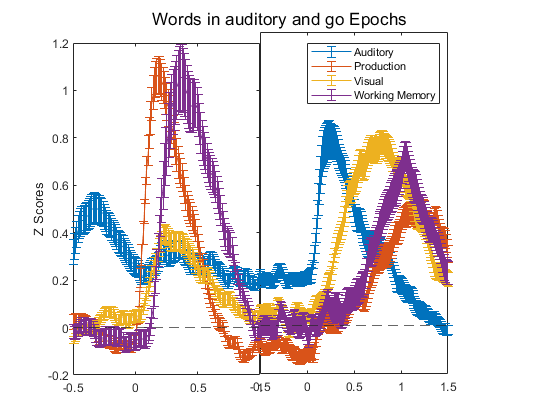

s = plot_together(Task, allSigZ, multi_idx, 'LSwords', ...
    {'AuditorywDelay','DelaywGo'},{[-0.5,1],[-0.5,1.5]});
sgtitle('Words in auditory and go Epochs')
ylabel(s(1),"Z Scores")
legend("Auditory","Production","Visual","Working Memory")

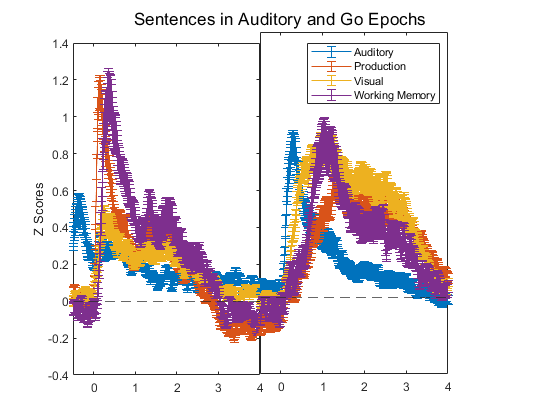


s = plot_together(Task, allSigZ, multi_idx, 'LSsentences', ...
    {'AuditorywDelay','DelaywGo'},{[-0.5,4],[-0.5,4]});
sgtitle('Sentences in Auditory and Go Epochs')
ylabel(s(1),"Z Scores")
legend("Auditory","Production","Visual","Working Memory")


%idx=SM

## where are the Ws?

% Sensory motor electrodes
histSig = sigMatChansLoc.LSwords.AuditorywDelay;
histSig(cellfun(@isempty,histSig))=[];

locations = elecHist(histSig);
insulaLocs = [];
for i=find(contains([locations.Name],'insula'))
    insulaLocs = [insulaLocs; locations(i).Elecs(:)];
end
insulaLocs_LSR = intersect(sigChans.LSwords.Response,insulaLocs); % convert from all elec space to idx space
insulaLocs_SM = intersect(SM,insulaLocs);
insulaLocs_PROD = intersect(PROD,insulaLocs);

% conds = {'LSwords', 'LMwords', 'JLwords'};
% figure
% ax = plot_together(Task, sigMatA, insulaLocs_PROD , conds, {'AuditorywDelay','DelaywGo'});
% title('DelaywGo')
% legend(conds)
% figure
% ax = plot_together(Task, sigMatA, PROD , conds, {'AuditorywDelay','DelaywGo'});
% title('DelaywGo')
% legend(conds)
% figure
% plot_together(Task, allSigZ, insulaLocs_PROD , {'LSwords'}, {'Response'});
% title('Response')


% plot_traces(Task,allSigZ,'LSwords','AuditorywDelay',insulaLocs_PROD,'PROD');
% plot_traces(Task,allSigZ,'LSwords','DelaywGo',insulaLocs_PROD,'PROD');
plot_traces(Task,allSigZ,'LSwords','Response',sigMatA,insulaLocs_LSR,'Insula');
% plot_traces(Task,allSigZ,'LSwords','DelaywGo',sigMatA,insulaLocs_LSD,'Insula');
% plot_traces(Task,allSigZ,'LSwords','DelaywGo',insulaLocs_SM,'SM');
% plot_traces(Task,allSigZ,'LSwords','Response',insulaLocs_SM,'SM');


% cfg color maps (Change later to check the actual figure)
map = [4 1 3 6 2 7 5];
pymap = [4 2 5 1]

pymap =      4     2     5     1


%% Manually label signals (AUD, SM, or PROD)
subj_labels=sigMatChansName.LSwords.AuditorywDelay;
cfg.hemisphere='l'; % b for both
grouping=zeros(length(subj_labels),1); % init
% for i=1:n_sigs
%     grouping(idx(Wi{i})) = map(i); % assign colors
% end
[grouping(idx)] = pymap(labels);

grouping =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D12\elec_recon\D12.FSAVERAGE
D12 110


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D14\elec_recon\D14.FSAVERAGE
D14 120


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D15\elec_recon\D15.FSAVERAGE
D15 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D16\elec_recon\D16.FSAVERAGE
D16 41


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D17\elec_recon\D17.FSAVERAGE
D17 114


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D18\elec_recon\D18.FSAVERAGE
D18 132


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D20\elec_recon\D20.FSAVERAGE
D20 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D22\elec_recon\D22.FSAVERAGE
D22 100


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D23\elec_recon\D23.FSAVERAGE
D23 121


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D24\elec_recon\D24.FSAVERAGE
D24 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D26\elec_recon\D26.FSAVERAGE
D26 60


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D27\elec_recon\D27.FSAVERAGE
D27 114


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D28\elec_recon\D28.FSAVERAGE
D28 108


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D29\elec_recon\D29.FSAVERAGE
D29 140


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D3\elec_recon\D3.FSAVERAGE
D3 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D30\elec_recon\D30.FSAVERAGE
D30 104


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D31\elec_recon\D31.FSAVERAGE
D31 160


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D32\elec_recon\D32.FSAVERAGE
D32 158


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D5\elec_recon\D5.FSAVERAGE
D5 48


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D53\elec_recon\D53.FSAVERAGE
D53 158


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D57\elec_recon\D57.FSAVERAGE
D57 178


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D59\elec_recon\D59.FSAVERAGE
D59 184


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D6\elec_recon\D6.FSAVERAGE
D6 96


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D60\elec_recon\D60.FSAVERAGE
D60 252


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D61\elec_recon\D61.FSAVERAGE
D61 232


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D65\elec_recon\D65.FSAVERAGE
D65 220


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D66\elec_recon\D66.FSAVERAGE
D66 182


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D69\elec_recon\D69.FSAVERAGE
D69 132


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D7\elec_recon\D7.FSAVERAGE
D7 102


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D70\elec_recon\D70.FSAVERAGE
D70 202


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D71\elec_recon\D71.FSAVERAGE
D71 162


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D73\elec_recon\D73.FSAVERAGE
D73 200


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D8\elec_recon\D8.FSAVERAGE
D8 110


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D9\elec_recon\D9.FSAVERAGE
D9 140
Loading: C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\fsaverage\surf\lh.pial.mat


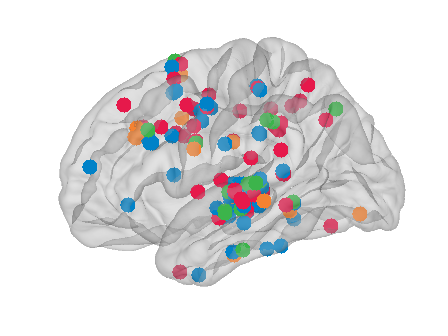


plot_subjs_on_average_grouping(subj_labels,grouping,'fsaverage',cfg);

% cfg.hemisphere='r';
% plot_subjs_on_average_grouping(subj_labels,grouping,'fsaverage',cfg);

## plot brains

ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D12\elec_recon\D12.FSAVERAGE
D12 110


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D14\elec_recon\D14.FSAVERAGE
D14 120


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D15\elec_recon\D15.FSAVERAGE
D15 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D16\elec_recon\D16.FSAVERAGE
D16 41


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D17\elec_recon\D17.FSAVERAGE
D17 114


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D18\elec_recon\D18.FSAVERAGE
D18 132


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D20\elec_recon\D20.FSAVERAGE
D20 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D22\elec_recon\D22.FSAVERAGE
D22 100


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D23\elec_recon\D23.FSAVERAGE
D23 121


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D24\elec_recon\D24.FSAVERAGE
D24 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D26\elec_recon\D26.FSAVERAGE
D26 60


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D27\elec_recon\D27.FSAVERAGE
D27 114


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D28\elec_recon\D28.FSAVERAGE
D28 108


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D29\elec_recon\D29.FSAVERAGE
D29 140


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D3\elec_recon\D3.FSAVERAGE
D3 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D30\elec_recon\D30.FSAVERAGE
D30 104


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D31\elec_recon\D31.FSAVERAGE
D31 160


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D32\elec_recon\D32.FSAVERAGE
D32 158


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D5\elec_recon\D5.FSAVERAGE
D5 48


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D53\elec_recon\D53.FSAVERAGE
D53 158


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D57\elec_recon\D57.FSAVERAGE
D57 178


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D59\elec_recon\D59.FSAVERAGE
D59 184


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D6\elec_recon\D6.FSAVERAGE
D6 96


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D60\elec_recon\D60.FSAVERAGE
D60 252


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D61\elec_recon\D61.FSAVERAGE
D61 232


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D65\elec_recon\D65.FSAVERAGE
D65 220


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D66\elec_recon\D66.FSAVERAGE
D66 182


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D69\elec_recon\D69.FSAVERAGE
D69 132


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D7\elec_recon\D7.FSAVERAGE
D7 102


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D70\elec_recon\D70.FSAVERAGE
D70 202


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D71\elec_recon\D71.FSAVERAGE
D71 162


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D73\elec_recon\D73.FSAVERAGE
D73 200


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D8\elec_recon\D8.FSAVERAGE
D8 110


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D9\elec_recon\D9.FSAVERAGE
D9 140
Loading: C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\fsaverage\surf\lh.pial.mat


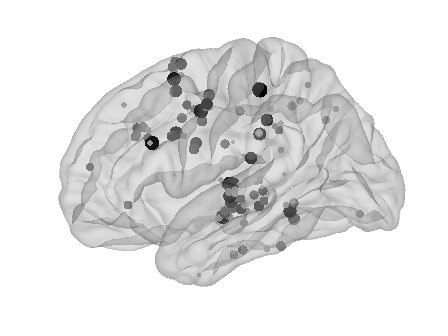

ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D12\elec_recon\D12.FSAVERAGE
D12 110


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D14\elec_recon\D14.FSAVERAGE
D14 120


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D15\elec_recon\D15.FSAVERAGE
D15 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D16\elec_recon\D16.FSAVERAGE
D16 41


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D17\elec_recon\D17.FSAVERAGE
D17 114


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D18\elec_recon\D18.FSAVERAGE
D18 132


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D20\elec_recon\D20.FSAVERAGE
D20 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D22\elec_recon\D22.FSAVERAGE
D22 100


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D23\elec_recon\D23.FSAVERAGE
D23 121


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D24\elec_recon\D24.FSAVERAGE
D24 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D26\elec_recon\D26.FSAVERAGE
D26 60


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D27\elec_recon\D27.FSAVERAGE
D27 114


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D28\elec_recon\D28.FSAVERAGE
D28 108


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D29\elec_recon\D29.FSAVERAGE
D29 140


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D3\elec_recon\D3.FSAVERAGE
D3 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D30\elec_recon\D30.FSAVERAGE
D30 104


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D31\elec_recon\D31.FSAVERAGE
D31 160


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D32\elec_recon\D32.FSAVERAGE
D32 158


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D5\elec_recon\D5.FSAVERAGE
D5 48


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D53\elec_recon\D53.FSAVERAGE
D53 158


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D57\elec_recon\D57.FSAVERAGE
D57 178


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D59\elec_recon\D59.FSAVERAGE
D59 184


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D6\elec_recon\D6.FSAVERAGE
D6 96


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D60\elec_recon\D60.FSAVERAGE
D60 252


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D61\elec_recon\D61.FSAVERAGE
D61 232


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D65\elec_recon\D65.FSAVERAGE
D65 220


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D66\elec_recon\D66.FSAVERAGE
D66 182


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D69\elec_recon\D69.FSAVERAGE
D69 132


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D7\elec_recon\D7.FSAVERAGE
D7 102


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D70\elec_recon\D70.FSAVERAGE
D70 202


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D71\elec_recon\D71.FSAVERAGE
D71 162


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D73\elec_recon\D73.FSAVERAGE
D73 200


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D8\elec_recon\D8.FSAVERAGE
D8 110


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D9\elec_recon\D9.FSAVERAGE
D9 140
Loading: C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\fsaverage\surf\lh.pial.mat


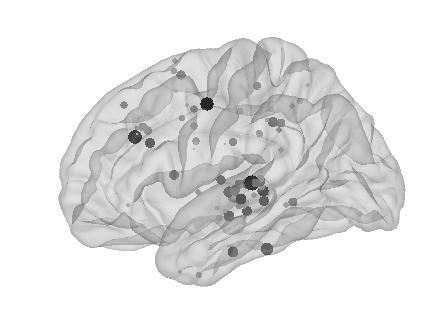

ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D12\elec_recon\D12.FSAVERAGE
D12 110


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D14\elec_recon\D14.FSAVERAGE
D14 120


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D15\elec_recon\D15.FSAVERAGE
D15 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D16\elec_recon\D16.FSAVERAGE
D16 41


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D17\elec_recon\D17.FSAVERAGE
D17 114


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D18\elec_recon\D18.FSAVERAGE
D18 132


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D20\elec_recon\D20.FSAVERAGE
D20 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D22\elec_recon\D22.FSAVERAGE
D22 100


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D23\elec_recon\D23.FSAVERAGE
D23 121


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D24\elec_recon\D24.FSAVERAGE
D24 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D26\elec_recon\D26.FSAVERAGE
D26 60


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D27\elec_recon\D27.FSAVERAGE
D27 114


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D28\elec_recon\D28.FSAVERAGE
D28 108


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D29\elec_recon\D29.FSAVERAGE
D29 140


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D3\elec_recon\D3.FSAVERAGE
D3 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D30\elec_recon\D30.FSAVERAGE
D30 104


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D31\elec_recon\D31.FSAVERAGE
D31 160


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D32\elec_recon\D32.FSAVERAGE
D32 158


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D5\elec_recon\D5.FSAVERAGE
D5 48


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D53\elec_recon\D53.FSAVERAGE
D53 158


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D57\elec_recon\D57.FSAVERAGE
D57 178


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D59\elec_recon\D59.FSAVERAGE
D59 184


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D6\elec_recon\D6.FSAVERAGE
D6 96


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D60\elec_recon\D60.FSAVERAGE
D60 252


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D61\elec_recon\D61.FSAVERAGE
D61 232


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D65\elec_recon\D65.FSAVERAGE
D65 220


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D66\elec_recon\D66.FSAVERAGE
D66 182


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D69\elec_recon\D69.FSAVERAGE
D69 132


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D7\elec_recon\D7.FSAVERAGE
D7 102


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D70\elec_recon\D70.FSAVERAGE
D70 202


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D71\elec_recon\D71.FSAVERAGE
D71 162


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D73\elec_recon\D73.FSAVERAGE
D73 200


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D8\elec_recon\D8.FSAVERAGE
D8 110


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D9\elec_recon\D9.FSAVERAGE
D9 140
Loading: C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\fsaverage\surf\lh.pial.mat


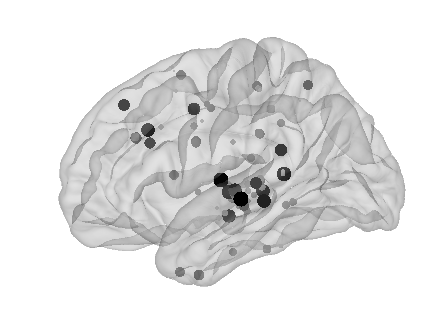

ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D12\elec_recon\D12.FSAVERAGE
D12 110


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D14\elec_recon\D14.FSAVERAGE
D14 120


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D15\elec_recon\D15.FSAVERAGE
D15 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D16\elec_recon\D16.FSAVERAGE
D16 41


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D17\elec_recon\D17.FSAVERAGE
D17 114


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D18\elec_recon\D18.FSAVERAGE
D18 132


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D20\elec_recon\D20.FSAVERAGE
D20 120


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D22\elec_recon\D22.FSAVERAGE
D22 100


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D23\elec_recon\D23.FSAVERAGE
D23 121


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D24\elec_recon\D24.FSAVERAGE
D24 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D26\elec_recon\D26.FSAVERAGE
D26 60


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D27\elec_recon\D27.FSAVERAGE
D27 114


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D28\elec_recon\D28.FSAVERAGE
D28 108


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D29\elec_recon\D29.FSAVERAGE
D29 140


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D3\elec_recon\D3.FSAVERAGE
D3 52


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D30\elec_recon\D30.FSAVERAGE
D30 104


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D31\elec_recon\D31.FSAVERAGE
D31 160


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D32\elec_recon\D32.FSAVERAGE
D32 158


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D5\elec_recon\D5.FSAVERAGE
D5 48


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D53\elec_recon\D53.FSAVERAGE
D53 158


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D57\elec_recon\D57.FSAVERAGE
D57 178


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D59\elec_recon\D59.FSAVERAGE
D59 184


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D6\elec_recon\D6.FSAVERAGE
D6 96


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D60\elec_recon\D60.FSAVERAGE
D60 252


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D61\elec_recon\D61.FSAVERAGE
D61 232


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D65\elec_recon\D65.FSAVERAGE
D65 220


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D66\elec_recon\D66.FSAVERAGE
D66 182


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D69\elec_recon\D69.FSAVERAGE
D69 132


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D7\elec_recon\D7.FSAVERAGE
D7 102


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D70\elec_recon\D70.FSAVERAGE
D70 202


ans = 0

Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D71\elec_recon\D71.FSAVERAGE
D71 162


ans = 0

Working on hemisphere: l
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D73\elec_recon\D73.FSAVERAGE
D73 200


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D8\elec_recon\D8.FSAVERAGE
D8 110


ans = 0

Working on hemisphere: l
Working on hemisphere: r
Storing electrode coordinates in FreeSurfer Average Brain space to C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\D9\elec_recon\D9.FSAVERAGE
D9 140
Loading: C:\Users\ae166\Documents\MATLAB\..\..\Box\ECoG_Recon\fsaverage\surf\lh.pial.mat


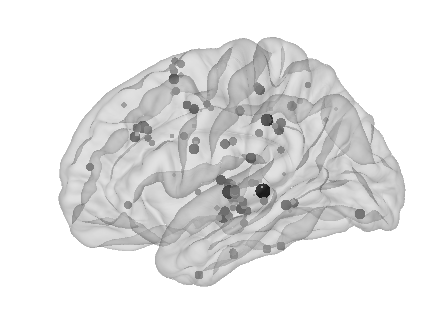

fnew = figure;
hems = 'l';
%for j = 1:2
%subj_labels=sigMatChansName.LSwords.AuditorywDelay;
grouping=zeros(length(subj_labels),1);
%grouping(AUD)=2; % why AUD2 here?
grouping(idx)=1; % why SM2 here?
%grouping(PROD)=4;
cfg.hemisphere=hems(1);
if ~strcmp(cfg.hemisphere,'b')
    Locs = find(~contains(subj_labels, upper(['-' cfg.hemisphere])));
    grouping(Locs) = 0;
else
    Locs = [];
end
ax=[];
for i = 1:n_sigs
    WI = W([find(setdiff(idx,Locs))],i);
    fig = plot_subjs_on_average_grouping(subj_labels,grouping,'fsaverage',cfg);
    fig.elec.SizeData = WI./max(WI).*200+0.0001;
    fig.elec.CData = ((([WI,WI,WI]./(-max(WI))+1).*0.7));
    ax1 = gca;
    delete(findobj(ax1, 'Type', 'text'))
    ax(i) = copyobj(ax1, fnew);
    subplot(1,n_sigs,i,ax(i),'Parent',fnew)
    title(ax(i),['W' sprintf('%d',i)])
end

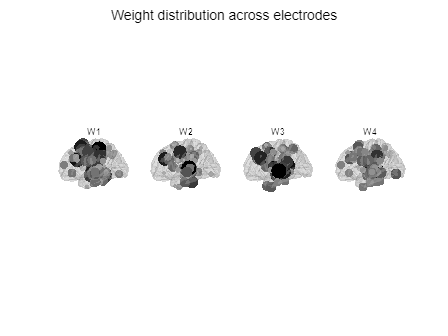

% end
%colorbar(ax(i))
sgtitle(fnew,'Weight distribution across electrodes')

plotTaskConds(Task,allSigZ,{'LSwords','LMwords','JLwords'}, ...
    'AuditorywDelay',idx,Wi);
plotTaskConds(Task,allSigZ,{'LSwords','LMwords','JLwords'}, ...
    'DelaywGo',idx,Wi);
plotTaskConds(Task,allSigZ,{'LSsentences','JLsentences'}, ...
    'AuditorywDelay',idx,Wi);
plotTaskConds(Task,allSigZ,{'LSsentences','JLsentences'}, ...
    'DelaywGo',idx,Wi);

plot_together(Task, allSigZ, multi_idx, 'LSsentences', ...
    {'AuditorywDelay','Response'},{[-0.5,4],[-1,4]});
sgtitle("Response Aligned Weights (LSsentences)")
legend("Auditory","Production","Visual","Working Memory")
plot_together(Task, allSigZ, multi_idx, 'LSwords', ...
    {'AuditorywDelay','DelaywGo'},{[-0.5,1],[-0.5,1.5]});
sgtitle("Go Aligned Weights (LSwords)")
plot_together(Task, allSigZ, multi_idx, 'LMwords', ...
    {'AuditorywDelay','DelaywGo'},{[-0.5,1],[-0.5,1.5]});
sgtitle("Go Aligned Weights (LMwords)")
plot_together(Task, allSigZ, multi_idx, 'JLwords', ...
    {'AuditorywDelay','DelaywGo'},{[-0.5,1],[-0.5,1.5]});
sgtitle("Go Aligned Weights (JLwords)")


function chans = getchans(sig,fields)
    fnames = string(fieldnames(sig)');
    chans = [];
    for i = fnames
        if any(strcmp(fields,i)) || isempty(intersect(fnames,fields))
            if isstruct(sig.(i))
                newset = getchans(sig.(i),fields);
            else
                newset = sig.(i);
            end
            chans = unique([chans;newset]);
        end
    end
end

function [tStart, tEnd] = getEpochFromName(Task,cond,field)
    for i=1:length(Task.Conds)
        if strcmp(Task.Conds(i).Name,cond)
            for j=1:length(Task.Conds(i).Field)
                if strcmp(Task.Conds(i).Field(j).Name,field)
                    tStart = Task.Conds(i).Field(j).Time(1);
                    tEnd = Task.Conds(i).Field(j).Time(2);
                    return
                end
            end
        end
    end
    error("No task and field combo found")
end

function plot_traces(Task,sig,cond,field,significance,idx,idxname,lockScale)
    global sigMatChansName
    figure
    tasksig = sig.(cond).(field);
    signif = significance.(cond).(field);
    if exist('idx','var')
        idxs = idx(idx <= size(tasksig,1));
        tasksig=tasksig(idxs,:);
        signif=signif(idxs,:);
    end
    if ~exist('idxname','var')
        prefix='Traces for ';
    else
        prefix=['Traces for ' idxname];
    end

    [tStart, tEnd] = getEpochFromName(Task,cond,field);
    tscale=linspace(tStart,tEnd,(tEnd-tStart)/10)/1000;
    numsig = size(tasksig,1);
    fsize = ceil(sqrt(numsig+1));
    yscale = [];
    s=[];
    for i = 1:numsig
        s(i)=subplot(fsize,fsize,i);
        plot(tscale,tasksig(i,:))
        title(sigMatChansName.(cond).(field)(idx(i)))
        yscale(i,:) = get(s(i),'Ylim');
        hold on
%         si = signif(i,:);
%         plot(tscale(si==1),si(si==1)*-0.5,"Color",'black','LineWidth',3)
    end
    s(i+1) = subplot(fsize,fsize,i+1);
    plot_signal(tasksig,tscale)
    if ~exist('lockScale','var')
        lockScale = 0;
    end
    for i=1:length(s)
        if i ~= length(s)
            si = signif(i,:);
            aBit = (yscale(i,2)-yscale(i,1))*0.05;
            plot(s(i),tscale(si==1),si(si==1)*yscale(i,1)-aBit,"Color",'black','LineWidth',5)
            ylim(s(i),[yscale(i,1)-(2*aBit),yscale(i,2)])
        end
        if lockScale
            ylim(s(i),[min(yscale(:,1)) max(yscale(:,2))])
        end
    end
    legend(s(1),'trace','significance','Location','SouthEast')
    sgtitle(sprintf('%s %s %s Aligned', prefix, cond, field))
end

function H=plotTaskConds(Task, sig, Conds, Epoch, idx, Wi, tunit)
    plotsig = {};
    for i = 1:length(Conds)
        plotsig{i} = sig.(Conds{i}).(Epoch);
    end
    [tstart, tend] = getEpochFromName(Task,Conds{1},Epoch);
    tscale=linspace(tstart,tend,(tend-tstart)/10);
    if ~exist('tunit','var')
        tunit = 'ms';
    end
    switch tunit
        case 'ms'
            tscale=tscale/1000;
        case 'us'
            tscale=tscale/1000000;
    end
    H=figure;
    xlabel('seconds')
    plot_signals(plotsig,idx,tscale)
    my_title = sprintf('%s Aligned',Epoch);
    title(my_title)
    legend(Conds)
    
    if exist('Wi','var')
        plot_weights(plotsig,idx,tscale,Wi)
        legend(Conds)
        sgtitle(sprintf('%s Weights',my_title))
    end
end

function s = plot_together(Task,sig,idxs,conds,fields,xlims,colors)
    
    s=[];
    yscale=[];
    n_sigs = size(fields,2);
    if n_sigs > 1
        figure
    end
    for i=1:n_sigs
        s(i) = subplot(1,n_sigs,i); %create and get handle to the subplot axes
        field=fields{i};
        if iscellstr(conds)
            for j=1:length(conds)
                cond = conds{j};
                [tStart, tEnd] = getEpochFromName(Task,cond,field);
                tscale=linspace(tStart,tEnd,(tEnd-tStart)/10)/1000;
                sigs = sig.(cond).(field);
                idx = idxs(idxs <= size(sigs,1));
                sigs = sigs(idx,:);   
                if exist('colors','var')
                    plot_signal(sigs,tscale,colors{j})
                else
                    plot_signal(sigs,tscale)
                end
                if j < length(conds)
                    hold on
                end
            end
        else
            if ~iscell(idxs)
                idxs = {idxs};
            end
            [tStart, tEnd] = getEpochFromName(Task,conds,field);
            tscale=linspace(tStart,tEnd,(tEnd-tStart)/10)/1000;
                for j=1:length(idxs)
                    idx = idxs{j};
                    sigs = sig.(conds).(field);
                    idx = idx(idx <= size(sigs,1));
                    sigs = sigs(idx,:);   
                    if exist('colors','var')
                        plot_signal(sigs,tscale,colors{j})
                    else
                        plot_signal(sigs,tscale)
                    end
                    if j < length(idxs)
                        hold on
                    end
                end
        end
        yscale(i,:) = get(s(i),'Ylim');
        if i == 1
            pos = get(s(1),'Position');
        elseif i > 1

            set(s(i),'YTick',[]);
            pos(1)=pos(1)+pos(3);
            set(s(i), 'Position', pos);
        end
        
        yline(s(i),0,'--')
        if exist('xlims','var')
            xlim(s(i),xlims{i})
        end
    end
    for i=1:length(s)
        if i ~= 1
            ylim(s(i),[max(yscale)])
            linkaxes([s(1),s(i)],'y')
    
        end
    end
end

function plot_weights(sigs, idx, tscale, Wi, colors)
% 
    figure;
    numsigs = length(Wi);
    figure;
    sqSize = ceil(sqrt(numsigs));
    for i=1:numsigs
        subplot(sqSize,sqSize,i);
        if exist('colors','var')
            plot_signals(sigs,idx(Wi{i},:),tscale,colors)
        else
            plot_signals(sigs,idx(Wi{i},:),tscale)
        end
        title(sprintf('%d',i))
    end
end

function plot_signals(sigs, Wi_idx, tscale, colors) 
% Takes a series of signals (sigs) and graphically compares the
% distribution of those signals over time (tscale). Those signals are
% weighted timepoint by timepoint by their nnmf in Wi_idx.
    for j=1:length(sigs)
        Wi_idx = Wi_idx(Wi_idx <= size(sigs{j},1)); % for conditions with fewer than max subjects ran
        sig = sigs{j}(Wi_idx,:);
        if ~exist('colors','var')
            plot_signal(sig,tscale)
        else
            plot_signal(sig,tscale,colors{j})
        end
        if j < length(sigs)
            hold on
        end
    end
end

function plot_signal(sig,tscale,color)
    trialMean = mean(sig);
    trialstd = std(sig,[],1);
    if ~exist('color','var')
        errorbar(tscale,trialMean,trialstd./sqrt(size(sig,1)))
    else
        errorbar(tscale,trialMean,trialstd./sqrt(size(sig,1)),color)
    end
end

function chanBinAll = loadTaskSubjectData(Task,Subject,task_dir)
    chanBinAll={};
    SNList=1:length(Subject);
    for iSN=1:length(SNList) %Subjects
        SN=SNList(iSN);
        chanIdx=Subject(SN).goodChannels;
        for iC=1:length(Task.Conds) %Conditions
            for iF=1:length(Task.Conds(iC).Field) %Epochs
                statsFile = [task_dir '\Stats\timePerm\' Subject(SN).Name '_' Task.Name '_' ...
                     Task.Conds(iC).Name '_' Task.Conds(iC).Field(iF).Name '_' Task.Base.Name '.mat'];
                 if ~isfile(statsFile)
                     disp([statsFile ' has not yet been created'])
                     continue % make this skip the whole subject
                 end
                load(statsFile, 'chanSig', 'ieegCARHG', 'ieegCARHGZ');          
                
                baseTimeRange=Task.Base.Time;
                baseTimeRange(1)=baseTimeRange(1)-500;
                baseTimeRange(2)=baseTimeRange(2)+500;
                TimeRange=Task.Conds(iC).Field(iF).Time;
                TimeRange(1)=TimeRange(1)-500;
                TimeRange(2)=TimeRange(2)+500;
                TimeLength=TimeRange(2)-TimeRange(1);
                
                totChanBlock=ceil(size(ieegCARHG,1)./60);
                iChan=0;
                chanSigBin=zeros(length(chanSig),1);
                tscale=linspace(TimeRange(1)+500,TimeRange(2)-500,size(ieegCARHG,3)-100);
                sigBinMat=zeros(size(ieegCARHG,1),size(ieegCARHG,3)-100);
                %     FigS=figure('Position', get(0, 'Screensize'));
                % figure
                for iChan=1:size(ieegCARHG,1) %min(60,size(ieegCARHG,1)-iChan);
                    
                    for iCl=1:length(chanSig{iChan}.actClust.Size)
                       % ii=sort(chanSig{iChan}.actClust.maxPermClust);
                       % if chanSig{iChan}.actClust.Size{iCl}>ii(990) % p<.01);
                        if chanSig{iChan}.actClust.Size{iCl}>chanSig{iChan}.actClust.perm95
                            chanSigBin(iChan)=1;
                            sigBinMat(iChan,chanSig{iChan}.actClust.Start{iCl}:chanSig{iChan}.actClust.Start{iCl}...
                                +(chanSig{iChan}.actClust.Size{iCl}-1))=ones(chanSig{iChan}.actClust.Size{iCl},1);
                        end
                    end                
                end
                chanBinAll{iSN}{iC}{iF}.matrix=sigBinMat;
                chanBinAll{iSN}{iC}{iF}.sigChans=chanSigBin;    
                chanBinAll{iSN}{iC}{iF}.Zs = ieegCARHGZ;
            end
        end
        display(iSN)
    end
end

function Wi = getSigMaxes(W)
    Wi = {};
    Wipos = [];
    [Wmax, maxIdx]=max(W,[],2);
    for i = 1:size(W,2)
        Wi{i} = find(maxIdx==i); % find max
        Wipos=find(W(:,i)>0); % find greater than 0
        Wi{i}=intersect(Wipos,Wi{i});
    end
end

function locBins = elecHist(chans,chanIdx)
    if ~exist('chanIdx','var')
        chanIdx = [1:length(chans)]';
    end
    locBins=[];

    binNames=unique(chans(chanIdx));
    
    for iB=1:length(binNames)
        locBins(iB).Name=binNames(iB);
        locBins(iB).Elecs=[];
        locBins(iB).Count=0;
        if contains(locBins(iB).Name,'lh')
            locBins(iB).Hemi=1;
        elseif contains(locBins(iB).Name,'rh')
            locBins(iB).Hemi=2;
        end
    end
    
    
    for iChan=1:length(chanIdx)
       for iB=1:length(locBins)
            tmp=strcmp(locBins(iB).Name,chans{chanIdx(iChan)});
            if tmp==1
                locBins(iB).Elecs=cat(1,locBins(iB).Elecs,chanIdx(iChan));
                locBins(iB).Count=locBins(iB).Count+1;
            end
        end
    end
    
    lhCount=0;
    rhCount=0;
    for iB=1:length(locBins)
        if locBins(iB).Hemi==1
            lhCount=lhCount+locBins(iB).Count;
        elseif locBins(iB).Hemi==2
            rhCount=rhCount+locBins(iB).Count;
        end
    end
    
    histVals=zeros(length(locBins),1);
    for iB=1:length(locBins)
        histVals(iB)=locBins(iB).Count;
    end
    figure;bar(histVals)
    xlabel('# corresponds to brain regions')

end

function [sigChans, sigMatA, allSigZ, sigMatChansName, sigMatChansLoc] = getChanSigs(Task, Subject, chanBinAll)
    sigMatChansLoc=struct;
    sigMatChansName=struct;
    sigChans=struct;
    sigMatA=struct;
    allSigZ=struct;
    AllSigWMIdx=[];
    
    for iC=1:size(chanBinAll{1},2) 
        cond = Task.Conds(iC).Name;
        for iF=1:size(chanBinAll{1}{iC},2) % the first subject's field length
            allSigZt=[];
            sigMatAt=[];
            sigChanst=[];
            elecCounter=0;
            field = Task.Conds(iC).Field(iF).Name;
            for iSN=1:size(chanBinAll,2)
                if iF > size(chanBinAll{iSN}{iC},2)
                    continue
                end
                sigMatChansCounter=0;
                ieegCARHGZ = chanBinAll{iSN}{iC}{iF}.Zs;
                allSigZt=cat(1,allSigZt,sq(mean(ieegCARHGZ(:,:,51:size(ieegCARHGZ,3)-50),2)));
                sigIdxGC=find(chanBinAll{iSN}{iC}{iF}.sigChans==1);
                % get rid of WM
                [nonWMIdx, nonWMIdxGC]=setdiff(Subject(iSN).goodChannels,Subject(iSN).WM);
                [WMIdx, WMIdxGC]=intersect(Subject(iSN).goodChannels,Subject(iSN).WM);
                chanIdx=intersect(sigIdxGC,nonWMIdxGC);
                AllSigWMIdx=cat(1,AllSigWMIdx,WMIdxGC);
                % chanIdx=setdiff(chanIdx,Subject(iSN).WM);
                %  chanIdx2=
                %sigMat=cat(1,sigMat,chanBinAll{iSN}{iC}{iF}.matrix(chanIdx,:));
               sigMatAt=cat(1,sigMatAt,chanBinAll{iSN}{iC}{iF}.matrix(:,:));
                %  sigMatAll=cat(1,sigMatAll,sigMatA);
               sigChanst=cat(1,sigChanst,chanIdx+elecCounter);
                for iChan=1:length(Subject(iSN).goodChannels)
                    sigMatChansName.(cond).(field){elecCounter+1}=Subject(iSN).ChannelInfo(Subject(iSN).goodChannels(iChan)).Name;
                    sigMatChansLoc.(cond).(field){elecCounter+1}=Subject(iSN).ChannelInfo(Subject(iSN).goodChannels(iChan)).Location;
                    elecCounter=elecCounter+1;
                  %  sigMatChansCounter=sigMatChansCounter+1;
                end
               % elecCounter=elecCounter+size(chanBinAll{iSN}{iC}{iF}.matrix,1);
            end
            allSigZ.(cond).(field)=allSigZt;
            sigMatA.(cond).(field)=sigMatAt;
            sigChans.(cond).(field)=sigChanst;
    
        end
        display(iC)
    end
end

function H = plot_timesig(Task, in_sig, Cond, Epoch, idx, W, my_y)
    [tstart, tend] = getEpochFromName(Task,Cond,Epoch);
    tscale=linspace(tstart,tend,(tend-tstart)/10)/1000;
    H = figure;
    % sig=allSigZ.LSwords.AuditorywDelay;
    my_title = sprintf("%s %s",Cond,Epoch);
    sig = in_sig.(Cond).(Epoch);
    if exist('idx','var')
        sig = sig(idx,:);
    end
    if exist('W','var')
        for i = 1:length(W)
            plot(tscale,mean(sig(W{i},:)),'LineWidth',2)
            hold on
        end
    else
        plot(tscale,mean(sig),'LineWidth',2)
    end
    axis('tight')
    ylim([-0.2 1])
    xlabel('Time (sec)')
    if exist('my_y','var')
        ylabel(my_y)
        title(sprintf("%ss for %s", my_y, my_title))
    else
        ylabel('Z score')
        title(sprintf("Z scores for %s", my_title))
    end
end